%Aufgabe A

close all;
clear all;

A = 2.5; %Amplitude
f = 10; %Frequenz
t = 0:0.0001:4*pi; %Zeitschritte, Zeitspanne
y = A*sin(2*pi*f*t); %Funktion

plot(t,y);
axis([0,0.2,-2.5,+2.5]); %x-Achse von 0 bis 0.2
grid on;
set(gca, 'FontSize', 14);
xlabel('Zeit [s]');
ylabel('Amplitude [V]');
title('Sinusschwingung');
hold on;
hold off;


%Aufgabe B
t = 0:0.0001:4*pi;
f = 10;
y1 = 2.5*sin(2*pi*f*t);
y2 = 2.5*sin(2*pi*f*t+pi/4); %Phasenverschiebung von pi/4 (45°)
hold on
grid on
plot(t,y1,'b-'); %Blau plotten
plot(t,y2,'r-'); %Rot plotten
axis([0,0.2,-2.5,+2.5]);
title('Sinusplot');
xlabel('Zeit');
ylabel('Blau: f(t), Rot: f(t+45*)');


figure(); 
hold on;

subplot(2,2,1);
x = 0:0.01:10;
y = sin(x);
plot(x,y);
hold on
title('sin(x)');
grid on;
hold off

subplot(2,2,2);
y = sin(y);
plot(x,y);
hold on
title('cos(x)');
grid on;
hold off

%Semi Log
subplot(2,2,3);
y = x.*x;
semilogy(x,y);
hold on
title('x^2 (Semi-log)');
grid on;
hold off

%Logarithmisch
subplot(2,2,4);
y = x.*x;
loglog(x,y);
hold on
title('x^2 (log)');
grid on;
hold off

%Aufgabe D
close all
clear all
num = [1 1]; %s+1 / Zähler
den = [2 4 5]; %Nenner
G = tf(num,den); %Transfer Function / Übertragungsfunktion
printsys(num,den,'s'); %Funktion mit s darstellen
pzmap(G);

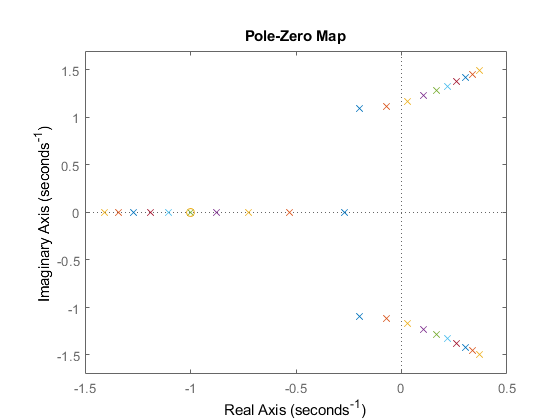

%Aufgabe E
num = [1 1]; %s+1 / Zähler

for i=1:10
    den = [3 2 4 i]; %variabler Nenner
    G = tf(num,den); %Transfer Function / Übertragungsfunktion
    pzmap(G);
    hold on;
    axis([-1.5 0.5 -1.7 1.7])
    
end